# SIMULACIÓN SISTEMAS MISO / SIMO / MIMO EN UNA CELDA LTE

clc;
clear all;
close all

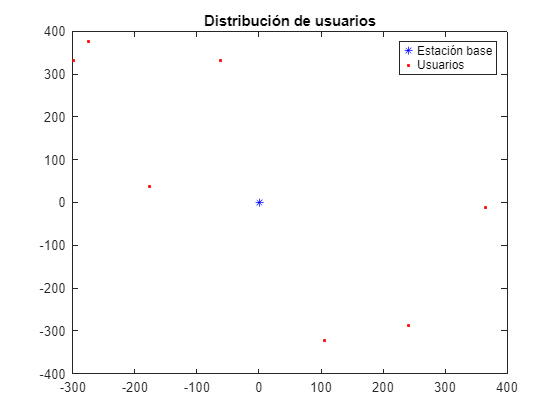

% Parámetros del sistema
K = 10;         % Numero de usuarios
lado_x = 800;   % Area de 800x800
lado_y = 800;
fd = 50;        % Frecuencia doppler
B = 10e6;       % Ancho de banda 
f = 1.8*10^9;   % Frecuencia de trabajo
Ts = 1/B;       % Tiempo de simbolo
N0 = 10^-20;    % Densidad espectral de potencia
Ptx = 20;       % Potencia de transmisión
sigma_sh = 1.5; % Desviación típica del shadowing en dB
Nsim = 1e6;     % Número de simulaciones

% Modulaciones y codificaciones
M1 = 64; R1 = 7/8; g1 = 10^(1.5/10);  % 64QAM, 7/8
M2 = 16; R2 = 3/4; g2 = 10^(4/10);   % 16QAM, 3/4

% Generamos el escenario
[Pos_BS, Pos_MS, dist_BS_MS, snr, SNR] = generar_escenario(K, lado_x, lado_y, Ptx, f, B, N0, sigma_sh);

% Visualizar distribucion
plot(Pos_BS,'*b');
hold on
plot(Pos_MS,'.r');
legend('Estación base', 'Usuarios');
title('Distribución de usuarios');

## Sistema MIMO 4x4 (canal conocido solo en Rx)

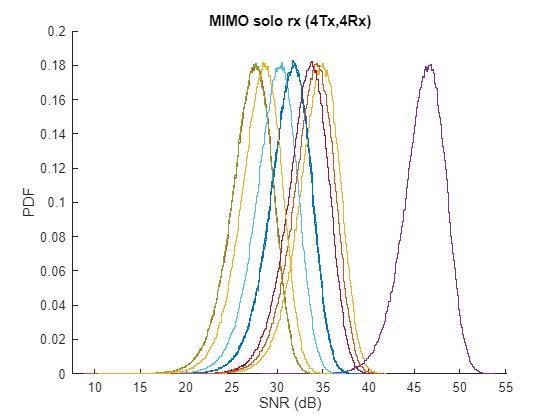

Mtx = 4; Mrx = 4;
h_eq_MIMO_rx = zeros(K, Nsim);

for k = 1:K
    % Generar canal
    h_eq_MIMO_rx(k,:) = generar_canal('MIMO_rx', snr(k), Mtx, Mrx, Nsim, Ptx);
end

% 64QAM
snr_MIMO_rx_64 = abs(h_eq_MIMO_rx).^2 * g1;
BER_MIMO_rx_64 = 0.2 * exp(-snr_MIMO_rx_64./(M1-1));
tasa_MIMO_rx_64 = B * R1 * log2(M1) * (BER_MIMO_rx_64 < 1e-3);

% 16QAM
snr_MIMO_rx_16 = abs(h_eq_MIMO_rx).^2 * g2;
BER_MIMO_rx_16 = 0.2 * exp(-snr_MIMO_rx_16./(M2-1));
tasa_MIMO_rx_16 = B * R2 * log2(M2) * (BER_MIMO_rx_16 < 1e-3);

% PDF
figure;
hold on;
for k = 1:K
    histogram(10*log10(snr_MIMO_rx_64(k,:)), 'Normalization', 'pdf', 'DisplayStyle', 'stairs');
end
title('MIMO solo rx (4Tx,4Rx)');
xlabel('SNR (dB)'); ylabel('PDF');



% SNR, BER y tasa por cada usuario
disp('--- MISO (4Tx,1Rx) ---');

--- MISO (4Tx,1Rx) ---


disp('******** 64QAM y R=7/8 ********');

******** 64QAM y R=7/8 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MIMO_rx_64(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MIMO_rx_64(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MIMO_rx_64(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 31.7798


BER: 8.3065e-05


Tasa: 51.8336Mbps


Usuario 2:


SNR(dB): 27.6417


BER: 0.0016746


Tasa: 41.9853Mbps


Usuario 3:


SNR(dB): 34.9863


BER: 6.2969e-06


Tasa: 52.4495Mbps


Usuario 4:


SNR(dB): 46.5914


BER: 4.8146e-12


Tasa: 52.5Mbps


Usuario 5:


SNR(dB): 27.5994


BER: 0.0017136


Tasa: 41.7691Mbps


Usuario 6:


SNR(dB): 30.2811


BER: 0.0002698


Tasa: 50.473Mbps


Usuario 7:


SNR(dB): 33.7458


BER: 1.6653e-05


Tasa: 52.3587Mbps


Usuario 8:


SNR(dB): 31.8568


BER: 8.1096e-05


Tasa: 51.8613Mbps


Usuario 9:


SNR(dB): 34.3816


BER: 9.4855e-06


Tasa: 52.4194Mbps


Usuario 10:


SNR(dB): 28.6367


BER: 0.00086667


Tasa: 46.5685Mbps


disp('******** 16QAM y R=3/4 ********');

******** 16QAM y R=3/4 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MIMO_rx_16(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MIMO_rx_16(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MIMO_rx_16(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 34.2798


BER: 4.5378e-08


Tasa: 29.9997Mbps


Usuario 2:


SNR(dB): 30.1417


BER: 1.7084e-06


Tasa: 29.9922Mbps


Usuario 3:


SNR(dB): 37.4863


BER: 8.39e-10


Tasa: 30Mbps


Usuario 4:


SNR(dB): 49.0914


BER: 2.736e-42


Tasa: 30Mbps


Usuario 5:


SNR(dB): 30.0994


BER: 1.7446e-06


Tasa: 29.9917Mbps


Usuario 6:


SNR(dB): 32.7811


BER: 1.9735e-07


Tasa: 29.9987Mbps


Usuario 7:


SNR(dB): 36.2458


BER: 2.6016e-09


Tasa: 30Mbps


Usuario 8:


SNR(dB): 34.3568


BER: 5.5734e-08


Tasa: 29.9998Mbps


Usuario 9:


SNR(dB): 36.8816


BER: 8.0058e-10


Tasa: 30Mbps


Usuario 10:


SNR(dB): 31.1367


BER: 7.3607e-07


Tasa: 29.9966Mbps


## Sistema MIMO 4x4 (canal conocido en Tx y Rx)

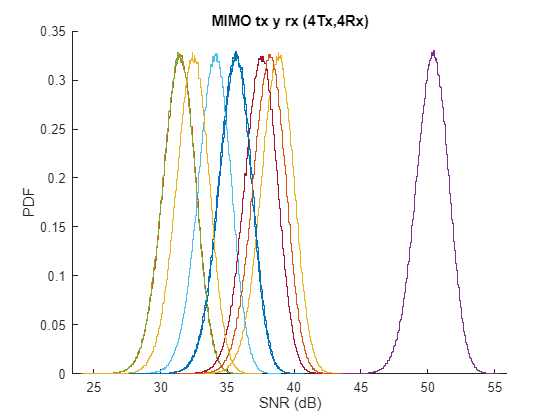

Mtx = 4; Mrx = 4;
h_eq_MIMO_txrx = zeros(K, Nsim);

for k = 1:K
    % Generar canal
    h_eq_MIMO_txrx(k,:) = generar_canal('MIMO_txrx',snr(k), Mtx, Mrx, Nsim, Ptx);
end

% 64QAM
snr_MIMO_txrx_64 = abs(h_eq_MIMO_txrx).^2 * g1;
BER_MIMO_txrx_64 = 0.2 * exp(-snr_MIMO_txrx_64./(M1-1));
tasa_MIMO_txrx_64 = B * R1 * log2(M1) * (BER_MIMO_txrx_64 < 1e-3);

% 16QAM
snr_MIMO_txrx_16 = abs(h_eq_MIMO_txrx).^2 * g2;
BER_MIMO_txrx_16 = 0.2 * exp(-snr_MIMO_txrx_16./(M2-1));
tasa_MIMO_txrx_16 = B * R2 * log2(M2) * (BER_MIMO_txrx_16 < 1e-3);

% PDF
figure;
hold on;
for k = 1:K
    histogram(10*log10(snr_MIMO_txrx_64(k,:)), 'Normalization', 'pdf', 'DisplayStyle', 'stairs');
end
title('MIMO tx y rx (4Tx,4Rx)');
xlabel('SNR (dB)'); ylabel('PDF');


% SNR, BER y tasa por cada usuario
disp('******** 64QAM y R=7/8 ********');

******** 64QAM y R=7/8 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MIMO_txrx_64(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MIMO_txrx_64(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MIMO_txrx_64(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 35.6582


BER: 8.9454e-12


Tasa: 52.5Mbps


Usuario 2:


SNR(dB): 31.5176


BER: 3.1589e-07


Tasa: 52.4996Mbps


Usuario 3:


SNR(dB): 38.8681


BER: 1.8683e-18


Tasa: 52.5Mbps


Usuario 4:


SNR(dB): 50.4705


BER: 1.108e-158


Tasa: 52.5Mbps


Usuario 5:


SNR(dB): 31.4829


BER: 3.5388e-07


Tasa: 52.4995Mbps


Usuario 6:


SNR(dB): 34.16


BER: 6.7258e-10


Tasa: 52.5Mbps


Usuario 7:


SNR(dB): 37.6309


BER: 2.3669e-14


Tasa: 52.5Mbps


Usuario 8:


SNR(dB): 35.7333


BER: 6.0547e-11


Tasa: 52.5Mbps


Usuario 9:


SNR(dB): 38.259


BER: 3.0723e-16


Tasa: 52.5Mbps


Usuario 10:


SNR(dB): 32.5139


BER: 4.015e-08


Tasa: 52.4999Mbps


disp('******** 16QAM y R=3/4 ********');

******** 16QAM y R=3/4 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MIMO_txrx_16(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MIMO_txrx_16(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MIMO_txrx_16(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 38.1582


BER: 1.436e-45


Tasa: 30Mbps


Usuario 2:


SNR(dB): 34.0176


BER: 8.7991e-22


Tasa: 30Mbps


Usuario 3:


SNR(dB): 41.3681


BER: 1.2434e-91


Tasa: 30Mbps


Usuario 4:


SNR(dB): 52.9705


BER: 0


Tasa: 30Mbps


Usuario 5:


SNR(dB): 33.9829


BER: 2.0815e-20


Tasa: 30Mbps


Usuario 6:


SNR(dB): 36.66


BER: 3.8887e-34


Tasa: 30Mbps


Usuario 7:


SNR(dB): 40.1309


BER: 1.9733e-60


Tasa: 30Mbps


Usuario 8:


SNR(dB): 38.2333


BER: 6.167e-34


Tasa: 30Mbps


Usuario 9:


SNR(dB): 40.759


BER: 4.4534e-74


Tasa: 30Mbps


Usuario 10:


SNR(dB): 35.0139


BER: 2.5282e-21


Tasa: 30Mbps


## Sistema SIMO 1x4

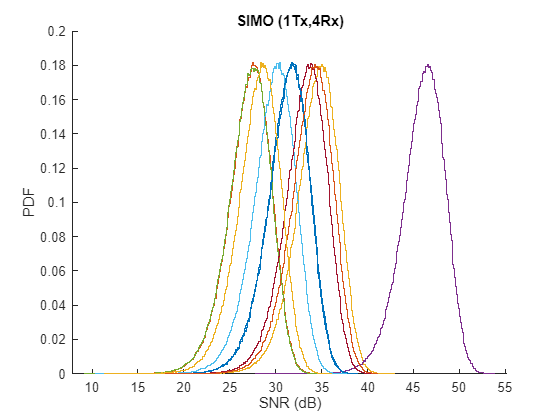

Mtx = 1; Mrx = 4;
h_eq_SIMO = zeros(K, Nsim);

for k = 1:K
    % Generar canal
    h_eq_SIMO(k,:) = generar_canal('SIMO', snr(k), Mtx, Mrx, Nsim, Ptx);
end

% 64QAM
snr_SIMO_64 = abs(h_eq_SIMO).^2 * g1;
BER_SIMO_64 = 0.2 * exp(-snr_SIMO_64./(M1-1));
tasa_SIMO_64 = B * R1 * log2(M1) * (BER_SIMO_64 < 1e-3);

% 16QAM
snr_SIMO_16 = abs(h_eq_SIMO).^2 * g2;
BER_SIMO_16 = 0.2 * exp(-snr_SIMO_16./(M2-1));
tasa_SIMO_16 = B * R2 * log2(M2) * (BER_SIMO_16 < 1e-3);

% PDF
figure;
hold on;
for k = 1:K
    histogram(10*log10(snr_SIMO_64(k,:)), 'Normalization', 'pdf', 'DisplayStyle', 'stairs');
end
title('SIMO (1Tx,4Rx)');
xlabel('SNR (dB)'); ylabel('PDF');


% SNR, BER y tasa por cada usuario
disp('******** 64QAM y R=7/8 ********');

******** 64QAM y R=7/8 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_SIMO_64(k,:))))]);
    disp(['BER: ', num2str(mean(BER_SIMO_64(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_SIMO_64(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 31.7789


BER: 8.3939e-05


Tasa: 51.8251Mbps


Usuario 2:


SNR(dB): 27.6406


BER: 0.0016729


Tasa: 41.9901Mbps


Usuario 3:


SNR(dB): 34.9899


BER: 6.2355e-06


Tasa: 52.447Mbps


Usuario 4:


SNR(dB): 46.5933


BER: 1.336e-11


Tasa: 52.5Mbps


Usuario 5:


SNR(dB): 27.601


BER: 0.0017186


Tasa: 41.757Mbps


Usuario 6:


SNR(dB): 30.2781


BER: 0.00026949


Tasa: 50.4789Mbps


Usuario 7:


SNR(dB): 33.7525


BER: 1.7225e-05


Tasa: 52.3596Mbps


Usuario 8:


SNR(dB): 31.8577


BER: 7.9124e-05


Tasa: 51.8684Mbps


Usuario 9:


SNR(dB): 34.3819


BER: 9.96e-06


Tasa: 52.4162Mbps


Usuario 10:


SNR(dB): 28.632


BER: 0.00087101


Tasa: 46.5246Mbps


disp('******** 16QAM y R=3/4 ********');

******** 16QAM y R=3/4 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_SIMO_16(k,:))))]);
    disp(['BER: ', num2str(mean(BER_SIMO_16(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_SIMO_16(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 34.2789


BER: 3.4959e-08


Tasa: 29.9998Mbps


Usuario 2:


SNR(dB): 30.1406


BER: 1.727e-06


Tasa: 29.9903Mbps


Usuario 3:


SNR(dB): 37.4899


BER: 3.6247e-09


Tasa: 30Mbps


Usuario 4:


SNR(dB): 49.0933


BER: 1.0021e-38


Tasa: 30Mbps


Usuario 5:


SNR(dB): 30.101


BER: 2.1704e-06


Tasa: 29.9906Mbps


Usuario 6:


SNR(dB): 32.7781


BER: 2.0752e-07


Tasa: 29.9993Mbps


Usuario 7:


SNR(dB): 36.2525


BER: 7.7967e-09


Tasa: 29.9999Mbps


Usuario 8:


SNR(dB): 34.3577


BER: 2.1665e-08


Tasa: 29.9998Mbps


Usuario 9:


SNR(dB): 36.8819


BER: 2.0387e-09


Tasa: 30Mbps


Usuario 10:


SNR(dB): 31.132


BER: 7.4948e-07


Tasa: 29.9967Mbps


## Sistema MISO 4x1

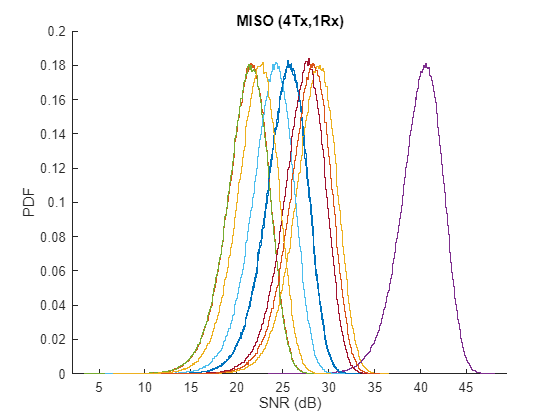

Mtx = 4; Mrx = 1;
h_eq_MISO = zeros(K, Nsim);

for k = 1:K
    % Generar canal
    h_eq_MISO(k,:) = generar_canal('MISO', snr(k), Mtx, Mrx, Nsim, Ptx);
    
end

% 64QAM
snr_MISO_64 = abs(h_eq_MISO).^2 * g1;
BER_MISO_64 = 0.2 * exp(-snr_MISO_64./(M1-1));
tasa_MISO_64 = B * R1 * log2(M1) * (BER_MISO_64 < 1e-3);

% 16QAM
snr_MISO_16 = abs(h_eq_MISO).^2 * g2;
BER_MISO_16= 0.2 * exp(-snr_MISO_16./(M2-1));
tasa_MISO_16 = B * R2 * log2(M2) * (BER_MISO_16 < 1e-3);

% PDF
figure;
hold on;
for k = 1:K
    histogram(10*log10(snr_MISO_64(k,:)), 'Normalization', 'pdf', 'DisplayStyle', 'stairs');
end
title('MISO (4Tx,1Rx)');
xlabel('SNR (dB)'); ylabel('PDF');


% SNR, BER y tasa por cada usuario
disp('--- MISO (4Tx,1Rx) ---');

--- MISO (4Tx,1Rx) ---


disp('******** 64QAM y R=7/8 ********');

******** 64QAM y R=7/8 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MISO_64(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MISO_64(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MISO_64(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 25.7589


BER: 0.0051766


Tasa: 27.6798Mbps


Usuario 2:


SNR(dB): 21.6181


BER: 0.032424


Tasa: 0.97083Mbps


Usuario 3:


SNR(dB): 28.9716


BER: 0.00069151


Tasa: 47.6538Mbps


Usuario 4:


SNR(dB): 40.5712


BER: 1.9976e-08


Tasa: 52.4997Mbps


Usuario 5:


SNR(dB): 21.5785


BER: 0.032868


Tasa: 0.91444Mbps


Usuario 6:


SNR(dB): 24.2665


BER: 0.011123


Tasa: 13.9193Mbps


Usuario 7:


SNR(dB): 27.7335


BER: 0.001586


Tasa: 42.5004Mbps


Usuario 8:


SNR(dB): 25.8372


BER: 0.0049522


Tasa: 28.3772Mbps


Usuario 9:


SNR(dB): 28.357


BER: 0.0010397


Tasa: 45.4926Mbps


Usuario 10:


SNR(dB): 22.6159


BER: 0.022601


Tasa: 3.5146Mbps


disp('******** 16QAM y R=3/4 ********');

******** 16QAM y R=3/4 ********


for k = 1:K
    disp(['Usuario ', num2str(k), ':']);
    disp(['SNR(dB): ', num2str(10*log10(mean(snr_MISO_16(k,:))))]);
    disp(['BER: ', num2str(mean(BER_MISO_16(k,:)))]);
    disp(['Tasa: ', num2str(mean(tasa_MISO_16(k,:))/1e6), 'Mbps']);
    disp(' ');
end

Usuario 1:


SNR(dB): 28.2589


BER: 9.6233e-06


Tasa: 29.955Mbps


Usuario 2:


SNR(dB): 24.1181


BER: 0.00025463


Tasa: 28.9029Mbps


Usuario 3:


SNR(dB): 31.4716


BER: 7.5528e-07


Tasa: 29.9969Mbps


Usuario 4:


SNR(dB): 43.0712


BER: 3.556e-19


Tasa: 30Mbps


Usuario 5:


SNR(dB): 24.0785


BER: 0.00026154


Tasa: 28.8687Mbps


Usuario 6:


SNR(dB): 26.7665


BER: 3.0745e-05


Tasa: 29.8512Mbps


Usuario 7:


SNR(dB): 30.2335


BER: 1.7954e-06


Tasa: 29.991Mbps


Usuario 8:


SNR(dB): 28.3372


BER: 8.6003e-06


Tasa: 29.9588Mbps


Usuario 9:


SNR(dB): 30.857


BER: 1.0422e-06


Tasa: 29.9948Mbps


Usuario 10:


SNR(dB): 25.1159


BER: 0.00012108


Tasa: 29.4663Mbps


#### MonteCarlo

% Parámetros del sistema
K = 10;         % Numero de usuarios
lado_x = 800;   % Area de 800x800
lado_y = 800;
fd = 50;        % Frecuencia doppler
B = 10e6;       % Ancho de banda 
f = 1.8*10^9;   % Frecuencia de trabajo
Ts = 1/B;       % Tiempo de simbolo
N0 = 10^-20;    % Densidad espectral de potencia
Ptx = 20;       % Potencia de transmisión
sigma_sh = 1.5; % Desviación típica del shadowing en dB
Nsim = 1e6;     % Número de simulaciones
BER_obj = 1e-3; % BER < 10^-3
NMC = 100;        % Número de realizaciones MonteCarlo

% Modulaciones y codificaciones
M1 = 64; R1 = 7/8; g1 = 10^(1.5/10);  % 64QAM, 7/8
M2 = 16; R2 = 3/4; g2 = 10^(4/10);    % 16QAM, 3/4

BER = zeros(NMC,K);
bits_tx = zeros(NMC,K);
BER_prom = zeros(1,NMC);
tasa = zeros(NMC,K);
tasa_total = zeros(1,NMC);

for r = 1:NMC
    % Generar escenario
    [Pos_BS, Pos_MS, dist_BS_MS, snr, SNR] = generar_escenario(K, lado_x, lado_y, Ptx, f, B, N0, sigma_sh);
    
    % Generar canal MISO
    Mtx = 4; Mrx = 1;
    h_MISO = canal_MISO(Pos_MS, Mtx, Mrx, snr, Nsim, Ptx);

    % Inicialización de vectores
    N_bits = log2(M1)*2*Nsim;
    btx = zeros(K, N_bits); brx = zeros(K, N_bits);
    y = zeros(1, Nsim); x_sched = zeros(1, Nsim); user_sched = zeros(1, Nsim);
    nb_v = zeros(K, 1); nb_v2 = zeros(K, 1);
    
    for n = 1:Nsim
        [~, m_opt] = max(abs(h_MISO(:, n)));
        
        user_sched(n) = m_opt;
        nb = nb_v(m_opt);
        
        % Calcular BER estimada
        ber1 = 0.2*exp(-abs(h_MISO(m_opt, n))^2*g1/(M1-1));
        ber2 = 0.2*exp(-abs(h_MISO(m_opt, n))^2*g2/(M2-1));
        
        if ber1 < BER_obj
            % MODULADOR 64QAM
            bits = round(rand(1, log2(M1)));
            btx(m_opt, (nb+1):(nb+log2(M1))) = bits;
            x_sched(n) = qammod(bits.', M1, 'InputType', 'bit');
            nb_v(m_opt) = nb + log2(M1);
            
            % Canal + ruido
            y(n) = awgn(h_MISO(m_opt, n) * x_sched(n), SNR(m_opt));
            
            % DEMODULADOR
            brx_bits = qamdemod(y(n)/h_MISO(m_opt, n), M1, 'OutputType', 'bit');
            brx(m_opt, (nb_v2(m_opt)+1):(nb_v2(m_opt)+log2(M1))) = brx_bits;
            nb_v2(m_opt) = nb_v2(m_opt) + log2(M1);
            
            bits_tx(r, m_opt) = bits_tx(r, m_opt) + log2(M1)*R1;
            
        elseif ber2 < BER_obj
            % MODULADOR 16QAM
            bits = round(rand(1, log2(M2)));
            btx(m_opt, (nb+1):(nb+log2(M2))) = bits;
            x_sched(n) = qammod(bits.', M2, 'InputType', 'bit');
            nb_v(m_opt) = nb + log2(M2);
            
            % Canal + ruido
            y(n) = awgn(h_MISO(m_opt, n) * x_sched(n), SNR(m_opt));
            
            % DEMODULADOR
            brx_bits = qamdemod(y(n)/h_MISO(m_opt, n), M2, 'OutputType', 'bit');
            brx(m_opt, (nb_v2(m_opt)+1):(nb_v2(m_opt)+log2(M2))) = brx_bits;
            nb_v2(m_opt) = nb_v2(m_opt) + log2(M2);
            
            bits_tx(r, m_opt) = bits_tx(r, m_opt) + log2(M2)*R2;
        end
    end
    
    % ESTIMAMOS LAS PRESTACIONES. BER y tasa tx
    disp(['REALIZACIÓN ', num2str(r)]);
    errors = abs(brx-btx); % diferencia entre los bits recibidos y transmitidos
    for i = 1:K
            tasa(r, i) = B * bits_tx(r,i)/Nsim/1e6;
            disp(['  Usuario ', num2str(i), ':', ...
                  '  BER = ', num2str(mean(errors(i,1:nb_v2(i)))), ...
                  '  Tasa = ', num2str(tasa(r,i)), ' Mbps', ...
                  '  Distancia = ', num2str(dist_BS_MS(i), '%.2f'), ' m']);
    end
    
    % Tasa total y BER en celda
    BER_prom(r) = mean(BER(r, BER(r,:)~=0));
    tasa_total(r) = sum(tasa(r,:));
    
    disp(' ');
    disp(['  BER promedio en celda: ', num2str(sum(BER_prom(:,r)))]);
    disp(['  Tasa total en celda: ', num2str(sum(tasa_total(:,r))), ' Mbps']);
    disp('----------------------------------------');
end

REALIZACIÓN 1


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.63 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 347.15 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 301.09 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 236.25 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 452.06 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 124.00 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 255.69 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 366.48 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 395.85 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 248.03 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 2


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 410.68 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.61 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 471.59 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.58 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 299.25 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 183.70 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 334.16 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.01 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 246.18 m
  Usuario 10:  BER = 0  Tasa = 52.4997 Mbps  Distancia = 150.61 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4997 Mbps


----------------------------------------


REALIZACIÓN 3


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 218.50 m
  Usuario 2:  BER = 0  Tasa = 52.4993 Mbps  Distancia = 179.33 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 418.12 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 182.39 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 278.99 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 233.57 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 520.44 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 422.11 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 369.93 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 361.85 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4993 Mbps


----------------------------------------


REALIZACIÓN 4


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 311.09 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 107.60 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 376.77 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 176.10 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 300.56 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 338.34 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 335.09 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 260.13 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 60.22 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 237.29 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 5


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 422.02 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.86 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 419.38 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 483.91 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 401.62 m
  Usuario 6:  BER = 0  Tasa = 52.498 Mbps  Distancia = 208.55 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 297.17 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 288.64 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 191.84 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 548.06 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.498 Mbps


----------------------------------------


REALIZACIÓN 6


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 412.63 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 278.12 m
  Usuario 3:  BER = 0  Tasa = 52.4803 Mbps  Distancia = 231.42 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 463.26 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 383.01 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.14 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.63 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 330.65 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 230.71 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 397.37 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4803 Mbps


----------------------------------------


REALIZACIÓN 7


  Usuario 1:  BER = 0  Tasa = 52.5 Mbps  Distancia = 102.55 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.20 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 323.60 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 249.48 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.67 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 228.40 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 334.06 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.35 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 239.32 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.49 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 8


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 458.85 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 300.22 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 84.53 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.14 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 71.66 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.94 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 472.93 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 226.81 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 322.73 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 316.12 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 9


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 238.09 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 398.62 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.23 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 128.20 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 403.50 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 232.54 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 413.43 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 315.89 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 327.15 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 156.86 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 10


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 440.07 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 513.28 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 192.84 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 153.43 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 479.36 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.84 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 37.41 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 407.85 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 323.22 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 218.39 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 11


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 224.83 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 133.24 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 367.52 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 165.03 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 404.91 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 525.95 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 103.83 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 63.26 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 382.23 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 378.62 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 12


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.06 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 252.17 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 372.91 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 142.78 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 135.38 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.15 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 236.95 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 219.30 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 456.95 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 306.33 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 13


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 349.70 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 240.29 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 253.17 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 206.16 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 381.45 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 469.99 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 536.14 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 60.93 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 294.46 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 498.44 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 14


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 354.82 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 439.65 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 127.24 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 341.34 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 362.43 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 172.77 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 402.81 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 421.97 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.18 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 190.36 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 15


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 445.75 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 426.04 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 213.74 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 69.30 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 295.67 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 142.16 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 452.14 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 506.42 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 134.86 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 360.41 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 16


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 353.79 m
  Usuario 2:  BER = 0  Tasa = 52.4997 Mbps  Distancia = 161.54 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 241.64 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 347.49 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 220.91 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 526.00 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 452.60 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 538.57 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 258.87 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 383.71 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4997 Mbps


----------------------------------------


REALIZACIÓN 17


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 151.82 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 331.22 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 417.88 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 370.48 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 131.70 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.42 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 426.99 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 105.72 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 305.47 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 379.58 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 18


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 394.15 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 98.34 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 130.46 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 298.77 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 67.27 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 235.72 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 549.97 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 453.22 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 52.67 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 309.49 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 19


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 232.85 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 298.60 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 399.53 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 318.36 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 291.48 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 248.61 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 24.15 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 180.81 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 113.61 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.97 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 20


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 255.74 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 336.29 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 139.75 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 256.42 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 161.71 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.97 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 414.64 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 227.88 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 145.01 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 513.31 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 21


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 281.37 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 73.26 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 251.96 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 321.73 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 49.96 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 148.74 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 268.34 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 239.49 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 350.68 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 392.39 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 22


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 430.60 m
  Usuario 2:  BER = 0  Tasa = 52.4948 Mbps  Distancia = 218.97 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 241.67 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 496.30 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 243.69 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 426.29 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.15 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 209.43 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.63 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 332.69 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4948 Mbps


----------------------------------------


REALIZACIÓN 23


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 284.74 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 455.20 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 138.89 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 249.63 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 231.77 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 306.75 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 291.83 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 353.27 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 391.89 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 354.58 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 24


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.51 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 87.01 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 156.27 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 260.09 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 137.24 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 96.35 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.63 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 430.78 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 146.10 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 306.35 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 25


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.40 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 230.43 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 437.35 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 409.00 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.60 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 257.84 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 235.81 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 374.19 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 329.58 m
  Usuario 10:  BER = 0  Tasa = 52.5 Mbps  Distancia = 68.18 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 26


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 337.91 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 159.24 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 448.88 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 277.87 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 209.48 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 370.48 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 311.15 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 248.18 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 43.37 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 271.30 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 27


  Usuario 1:  BER = 0  Tasa = 52.5 Mbps  Distancia = 104.19 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 494.79 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 336.25 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.94 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.78 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 380.54 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 204.28 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 204.10 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 272.77 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.09 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 28


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 256.75 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 308.71 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 368.20 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 132.47 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 299.37 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 415.29 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 345.49 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 235.71 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 461.08 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 314.35 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 29


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 144.65 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 323.41 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 188.49 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.65 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 199.63 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.60 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 274.28 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 183.62 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 129.22 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 406.17 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 30


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 268.45 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 318.97 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 176.94 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 480.31 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 473.52 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 376.65 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 408.27 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.29 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 75.16 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.48 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 31


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 241.88 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 500.10 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 504.47 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 473.80 m
  Usuario 5:  BER = 0  Tasa = 52.4769 Mbps  Distancia = 225.91 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 375.49 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 392.99 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 405.61 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 371.65 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.33 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4769 Mbps


----------------------------------------


REALIZACIÓN 32


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 470.46 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 86.90 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 242.24 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 394.66 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 322.38 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 319.77 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 172.68 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.95 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 202.13 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 444.05 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 33


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 317.75 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 55.45 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 345.79 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 416.63 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 405.60 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 456.99 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 237.47 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 440.82 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 162.73 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 90.12 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 34


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 337.24 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 426.49 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.88 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 277.68 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 294.20 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 410.11 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 260.03 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 398.57 m
  Usuario 9:  BER = 0  Tasa = 52.4821 Mbps  Distancia = 189.68 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 206.55 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4821 Mbps


----------------------------------------


REALIZACIÓN 35


  Usuario 1:  BER = 0  Tasa = 52.5 Mbps  Distancia = 92.77 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 194.04 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 146.20 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 395.75 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 428.83 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 505.02 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 363.21 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 336.54 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 245.78 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 203.80 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 36


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 151.51 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 475.41 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 436.30 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 424.28 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 383.72 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 18.76 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 372.93 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 194.98 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 329.60 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 153.83 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 37


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 288.66 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 321.71 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 316.65 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 48.54 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.07 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 227.70 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 314.82 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 206.23 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.30 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 272.18 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 38


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.14 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 379.14 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 299.92 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 165.47 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 457.61 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.31 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 66.30 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 308.58 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 82.37 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 243.68 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 39


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 294.84 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 284.25 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 397.03 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 214.72 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 312.97 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 116.31 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 286.77 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 190.75 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 146.61 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.96 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 40


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 397.21 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 458.05 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 392.13 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 280.83 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 226.71 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 418.32 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 496.48 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 152.14 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.12 m
  Usuario 10:  BER = 0  Tasa = 52.5 Mbps  Distancia = 77.20 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 41


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.97 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 389.74 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 403.05 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 215.88 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 73.41 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.38 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 119.07 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 331.62 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 273.37 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 351.26 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 42


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 70.43 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 132.38 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 364.78 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.55 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 91.73 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 365.10 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 41.86 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 324.41 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.50 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 136.53 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 43


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 337.45 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 312.72 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 116.27 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 85.18 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 248.73 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 418.03 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 290.24 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 300.42 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 114.35 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 350.00 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 44


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 280.07 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 395.06 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 410.80 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 232.59 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 355.39 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 297.22 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 126.68 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 445.16 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.02 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 163.70 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 45


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 122.35 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 151.49 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 198.88 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 368.61 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 332.35 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 89.71 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.44 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 471.64 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 244.34 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 261.74 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 46


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 357.03 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.44 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 312.37 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 425.74 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 363.52 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 375.56 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 262.06 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 116.21 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 270.19 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 212.20 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 47


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 174.22 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 112.52 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 281.98 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 186.40 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 187.20 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 74.14 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 350.25 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 210.67 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 215.22 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 376.74 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 48


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.45 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 309.22 m
  Usuario 3:  BER = 0  Tasa = 52.4476 Mbps  Distancia = 214.30 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 350.32 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 302.58 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 317.88 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 418.72 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 546.54 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 453.72 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 367.08 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4476 Mbps


----------------------------------------


REALIZACIÓN 49


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 366.99 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 196.67 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 170.93 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 295.96 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 428.80 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 362.99 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 138.36 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 335.85 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 333.63 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 278.44 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 50


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 475.25 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 368.04 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 387.99 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 244.24 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 109.46 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 349.58 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 286.84 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 128.99 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 246.41 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 203.43 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 51


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 334.20 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 431.13 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 299.01 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 178.79 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 457.73 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 73.72 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 544.11 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 162.85 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 349.12 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 169.18 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 52


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 344.15 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 357.05 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 488.66 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 237.60 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 207.31 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 453.34 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 127.79 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 494.04 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 299.11 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.78 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 53


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 437.43 m
  Usuario 2:  BER = 0  Tasa = 52.4461 Mbps  Distancia = 211.78 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 430.83 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 486.00 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.51 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 288.18 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 407.73 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.05 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.75 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 257.66 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4461 Mbps


----------------------------------------


REALIZACIÓN 54


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 447.68 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 210.34 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 147.04 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 441.74 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 351.63 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 310.52 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 107.06 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 296.60 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 226.51 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 237.01 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 55


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 340.40 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.03 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 296.05 m
  Usuario 4:  BER = 0  Tasa = 52.4999 Mbps  Distancia = 162.73 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 466.28 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 380.17 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 452.96 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.50 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 308.31 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 351.12 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4999 Mbps


----------------------------------------


REALIZACIÓN 56


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 304.25 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.87 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 439.97 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 355.17 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 513.90 m
  Usuario 6:  BER = 0  Tasa = 52.408 Mbps  Distancia = 223.71 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 286.79 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 476.09 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 506.34 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.08 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.408 Mbps


----------------------------------------


REALIZACIÓN 57


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 131.61 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 440.09 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 380.60 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 342.53 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 43.88 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 328.34 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 114.43 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 454.79 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 178.77 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 357.28 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 58


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.15 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 342.34 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 241.04 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 233.59 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 191.23 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 314.47 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 294.91 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 385.39 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 77.76 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.64 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 59


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.59 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 421.22 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 237.85 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 363.39 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 120.96 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 276.16 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 278.72 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 264.22 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 304.42 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 184.56 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 60


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 164.24 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 319.00 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 321.87 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 355.86 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.22 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 297.46 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 393.58 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.53 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 253.66 m
  Usuario 10:  BER = 0  Tasa = 52.5 Mbps  Distancia = 126.19 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 61


  Usuario 1:  BER = 0  Tasa = 52.5 Mbps  Distancia = 128.83 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 294.25 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 421.76 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 407.91 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 483.03 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 555.02 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 296.78 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 423.35 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 450.98 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 221.13 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 62


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 402.69 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 471.62 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 203.89 m
  Usuario 4:  BER = 0  Tasa = 52.4989 Mbps  Distancia = 180.29 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 419.07 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.42 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 334.89 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 224.30 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 359.39 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 362.15 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4989 Mbps


----------------------------------------


REALIZACIÓN 63


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 256.88 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 275.09 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 257.50 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 361.97 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 142.25 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 317.24 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 369.77 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 161.10 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 155.89 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 206.68 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 64


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 216.55 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 111.44 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 319.85 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.07 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 333.44 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 370.77 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 402.35 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 264.20 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 466.63 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 308.47 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 65


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 300.73 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 67.31 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 424.97 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 168.33 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 372.27 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 275.80 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.58 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 392.86 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 330.80 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 186.69 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 66


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 199.39 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 474.06 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.41 m
  Usuario 4:  BER = 0  Tasa = 52.4989 Mbps  Distancia = 201.57 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 202.02 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 427.39 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 369.57 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 305.92 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 335.76 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 239.12 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4989 Mbps


----------------------------------------


REALIZACIÓN 67


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 250.48 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 382.13 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 403.82 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 271.27 m
  Usuario 5:  BER = 0  Tasa = 52.4972 Mbps  Distancia = 207.66 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.82 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 210.36 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 469.61 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.72 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 225.75 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4972 Mbps


----------------------------------------


REALIZACIÓN 68


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 438.87 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.26 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 162.41 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 466.06 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 317.24 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 476.77 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 36.29 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.79 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 308.08 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.14 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 69


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 351.20 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 258.34 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 329.16 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 330.72 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 456.46 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 284.79 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 154.94 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 154.45 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 316.96 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 269.62 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 70


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 296.76 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 103.74 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 369.62 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.75 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 68.67 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 434.54 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 315.49 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 383.08 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 272.70 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.58 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 71


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 438.89 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 330.22 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 97.56 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 215.71 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 420.55 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 143.07 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 94.11 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 239.56 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 447.73 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 250.28 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 72


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 435.09 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 396.08 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 289.77 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 362.55 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 105.85 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 297.10 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 378.91 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 271.89 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 38.93 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 330.29 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 73


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 376.67 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 385.33 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.52 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 159.95 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 398.57 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 321.50 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.58 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 169.40 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 12.56 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 121.40 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 74


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 170.46 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 100.03 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 373.14 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 276.16 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 381.76 m
  Usuario 6:  BER = 0  Tasa = 52.5 Mbps  Distancia = 99.81 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 164.96 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 86.14 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 345.51 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 337.33 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 75


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 253.04 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.02 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 451.90 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 141.32 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 337.77 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 433.42 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 432.72 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 335.95 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 392.05 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 476.63 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 76


  Usuario 1:  BER = 0  Tasa = 52.4995 Mbps  Distancia = 154.37 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 406.97 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 361.08 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 333.71 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 341.48 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 365.90 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 377.36 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 363.29 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 351.37 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 457.48 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4995 Mbps


----------------------------------------


REALIZACIÓN 77


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 328.61 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 71.68 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 234.46 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 177.65 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 191.92 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.67 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.60 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 367.71 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 311.74 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 513.32 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 78


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 315.02 m
  Usuario 2:  BER = 0  Tasa = 52.5 Mbps  Distancia = 97.38 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 309.04 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 325.71 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.64 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 315.70 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 144.51 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.81 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 469.45 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 372.51 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 79


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 162.34 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 189.61 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 339.52 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 316.92 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 461.46 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 417.63 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 108.32 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 212.65 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 68.43 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 425.96 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 80


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 269.85 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 496.42 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 385.26 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 256.20 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 135.29 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 314.40 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 102.47 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 319.68 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 431.00 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 469.50 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 81


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 387.24 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 449.90 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 255.08 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 224.72 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 453.49 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 285.65 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 459.12 m
  Usuario 8:  BER = 0  Tasa = 52.5 Mbps  Distancia = 99.34 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 322.45 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 165.75 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 82


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 272.12 m
  Usuario 2:  BER = 0  Tasa = 52.4831 Mbps  Distancia = 182.50 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 312.86 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 422.09 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 242.75 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 309.21 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 355.62 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 451.32 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 217.34 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 329.55 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4831 Mbps


----------------------------------------


REALIZACIÓN 83


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 312.51 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 188.74 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 298.16 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 411.66 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 366.64 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 394.91 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 30.81 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 163.29 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 153.62 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.63 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 84


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.98 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 386.87 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.82 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 250.71 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 459.63 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 275.20 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 188.30 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 496.60 m
  Usuario 9:  BER = 0  Tasa = 52.5 Mbps  Distancia = 105.07 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 325.50 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 85


  Usuario 1:  BER = 0  Tasa = 52.4985 Mbps  Distancia = 177.37 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 207.51 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 252.58 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 341.65 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 446.21 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 528.64 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 240.61 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 343.20 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 384.08 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 267.13 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4985 Mbps


----------------------------------------


REALIZACIÓN 86


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 248.40 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 436.66 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 393.21 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 184.25 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 55.58 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 321.02 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 369.85 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 364.64 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 160.44 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 242.80 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 87


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 298.42 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 323.90 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 76.78 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 480.97 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 399.85 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 292.98 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 456.37 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 226.24 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 205.15 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 122.06 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 88


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 408.86 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 354.51 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 359.31 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 366.59 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 382.81 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 162.18 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 344.92 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 354.12 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 409.54 m
  Usuario 10:  BER = 0  Tasa = 52.4998 Mbps  Distancia = 145.23 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4998 Mbps


----------------------------------------


REALIZACIÓN 89


  Usuario 1:  BER = 0  Tasa = 52.5 Mbps  Distancia = 99.68 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 404.00 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 233.03 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 126.25 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 270.43 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 457.46 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 352.56 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 120.81 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 454.10 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 265.31 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 90


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 358.30 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 234.93 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 433.83 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 296.08 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 454.51 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 391.74 m
  Usuario 7:  BER = 0  Tasa = 52.4993 Mbps  Distancia = 161.58 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 263.07 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 435.58 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 423.77 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4993 Mbps


----------------------------------------


REALIZACIÓN 91


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 416.25 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.84 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 461.71 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 370.90 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 115.73 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 371.59 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 288.33 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 152.16 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 290.88 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 473.41 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 92


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 381.19 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 397.68 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 223.52 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 457.48 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 193.56 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 409.85 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 253.62 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 387.14 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 130.77 m
  Usuario 10:  BER = 0  Tasa = 52.5 Mbps  Distancia = 100.58 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 93


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.51 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 118.06 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 435.94 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 442.56 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 346.07 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 472.29 m
  Usuario 7:  BER = 0  Tasa = 52.5 Mbps  Distancia = 30.95 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 135.90 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 378.36 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 193.43 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 94


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 340.98 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 314.01 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 450.61 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 288.66 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 390.91 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 254.18 m
  Usuario 7:  BER = 0  Tasa = 52.497 Mbps  Distancia = 167.06 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 322.85 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 537.28 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 277.27 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.497 Mbps


----------------------------------------


REALIZACIÓN 95


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 448.94 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 302.41 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 251.51 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 473.38 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 267.89 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 388.24 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 272.63 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 332.50 m
  Usuario 9:  BER = 0  Tasa = 52.4995 Mbps  Distancia = 159.84 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 318.47 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4995 Mbps


----------------------------------------


REALIZACIÓN 96


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 244.76 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 447.10 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 250.12 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 348.12 m
  Usuario 5:  BER = 0  Tasa = 52.5 Mbps  Distancia = 80.50 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 542.37 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 221.43 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 315.21 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 348.19 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 277.11 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 97


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 406.27 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 189.47 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 75.43 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 216.86 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 259.56 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 127.76 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 367.49 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 316.78 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 382.52 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 412.78 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 98


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 268.35 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 348.68 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 320.03 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 259.57 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 393.72 m
  Usuario 6:  BER = 0  Tasa = 52.4561 Mbps  Distancia = 248.48 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 503.86 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 245.92 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 372.48 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 305.26 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.4561 Mbps


----------------------------------------


REALIZACIÓN 99


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 483.19 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 427.28 m
  Usuario 3:  BER = NaN  Tasa = 0 Mbps  Distancia = 349.68 m
  Usuario 4:  BER = 0  Tasa = 52.5 Mbps  Distancia = 57.66 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 335.29 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 386.80 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 395.14 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 278.08 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 404.39 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 275.13 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


REALIZACIÓN 100


  Usuario 1:  BER = NaN  Tasa = 0 Mbps  Distancia = 333.44 m
  Usuario 2:  BER = NaN  Tasa = 0 Mbps  Distancia = 256.78 m
  Usuario 3:  BER = 0  Tasa = 52.5 Mbps  Distancia = 82.30 m
  Usuario 4:  BER = NaN  Tasa = 0 Mbps  Distancia = 206.33 m
  Usuario 5:  BER = NaN  Tasa = 0 Mbps  Distancia = 249.17 m
  Usuario 6:  BER = NaN  Tasa = 0 Mbps  Distancia = 458.55 m
  Usuario 7:  BER = NaN  Tasa = 0 Mbps  Distancia = 276.66 m
  Usuario 8:  BER = NaN  Tasa = 0 Mbps  Distancia = 194.62 m
  Usuario 9:  BER = NaN  Tasa = 0 Mbps  Distancia = 347.78 m
  Usuario 10:  BER = NaN  Tasa = 0 Mbps  Distancia = 262.09 m


  BER promedio en celda: NaN


  Tasa total en celda: 52.5 Mbps


----------------------------------------


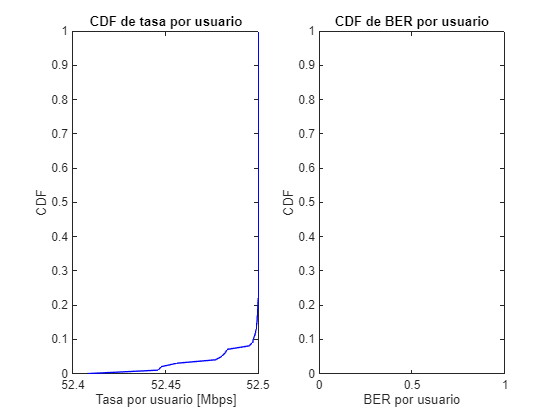


% CDFs
figure;
subplot(1,2,1);
tasa_ordenada = sort(tasa_total(:));
plot(tasa_ordenada, linspace(0,1,length(tasa_ordenada)), 'b-');
xlabel('Tasa por usuario [Mbps]'); ylabel('CDF');
title('CDF de tasa por usuario');

subplot(1,2,2);
ber_ordenada = sort(BER_prom(:));
plot(ber_ordenada, linspace(0,1,length(ber_ordenada)), 'r-');
xlabel('BER por usuario'); ylabel('CDF'); title('CDF de BER por usuario');